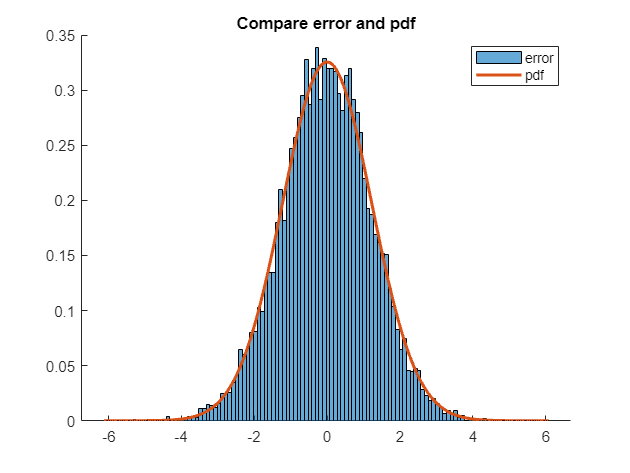

%%part e

% Generate a long true state sequence
N = 10000; % length
x_0 = 2; % prior mean
P_0 = 8; % prior covariance
Q = 1.5; % motion noise covariance
R = 3; % measurement noise covariance
A = 1; % xk = A*x_{k-1} + q
H = 1; % Yk = H*xk + r
X = genLinearStateSequence(x_0, P_0, A, Q, N);

% Generate a corresponding measurement sequence
Y = genLinearMeasurementSequence(X, H, R);

% Filter the measurement sequence using the Kalman filter
[x_hat, P_hat] = kalmanFilter(Y, x_0, P_0, A, Q, H, R);

% Calculate the estimation error
e = X(2:end) - x_hat;

% Calculate the estimated mean of the estimation error sequence
e_mean = mean(e);


x_range = [-5*sqrt(squeeze(P_hat(:,:,end))):0.1:5*sqrt(squeeze(P_hat(:,:,end)))];


% Plot a histogram of the estimation error
figure(1); clf; hold on;

% Normalize the histogram with the length of the sequence
histogram('BinEdges',x_range,'BinCounts',histcounts(e,x_range)/N,'Normalization','pdf');
% Error experience
% Here the Normalization parameter should be PDF

% Plot the pdf N(x;0, P_NIN)
pdf_N = normpdf(x_range, 0, sqrt(squeeze(P_hat(:,:,end))));
plot(x_range, pdf_N, 'LineWidth', 2);
legend('error','pdf')
title('Compare error and pdf')


%%%%%%%%%%%%%%%%%%%
% Generate the true state sequence
X = genLinearStateSequence(x_0, P_0, A, Q, N);

% Generate the measurement sequence
Y = genLinearMeasurementSequence(X, H, R);

% Filter the measurement sequence using the Kalman filter
[X, P, v, S] = vkalmanFilter(Y, x_0, P_0, A, Q, H, R);

% Estimate the mean of the innovation process
mean_v = mean(v);
disp('mean of v is:')

mean of v is:


disp(mean_v)

    0.0119



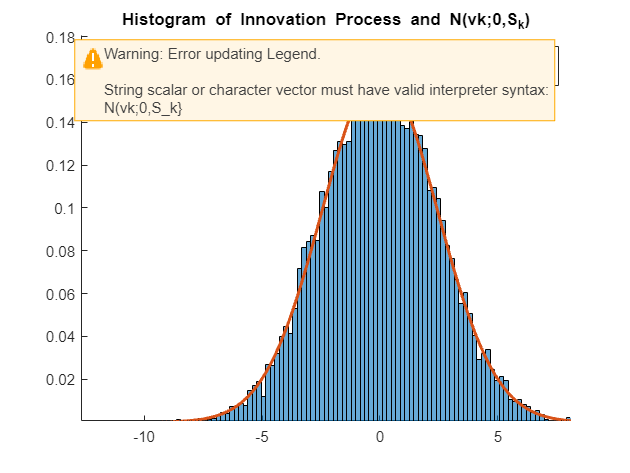


x_range = linspace(min(v), max(v), 100);
% Plot the histogram of the innovation process
figure(2); clf; hold on;
histogram(v, 'Normalization', 'pdf','BinEdges',x_range);
pdf_v = normpdf(x_range, 0, sqrt(S));
plot(x_range, pdf_v, 'LineWidth', 2);
title('Histogram of Innovation Process and N(vk;0,S_k)');
legend('Histogram','N(vk;0,S_k}');

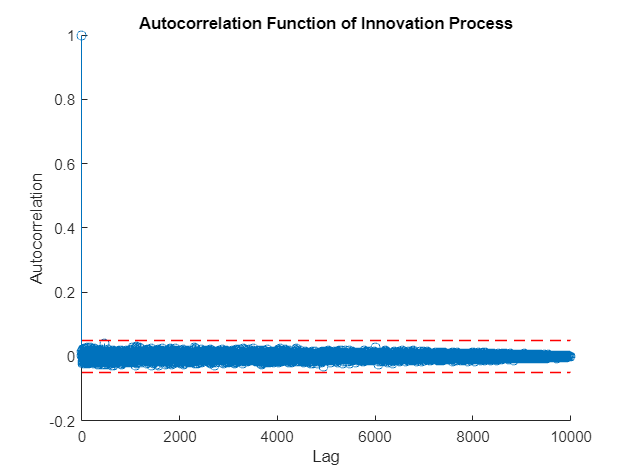


% Estimate the autocorrelation function of the innovation process
figure(4);clf;hold on;
acf_v = autocorr(v, N-1);

% Plot the autocorrelation function of the innovation process
figure(3); clf;hold on;
stem(0:N-1, acf_v);
title('Autocorrelation Function of Innovation Process');
xlabel('Lag');
ylabel('Autocorrelation');
% Add +/-0.05 lines
plot([0, N-1], [0.05, 0.05], 'r--', 'LineWidth', 1);
plot([0, N-1], [-0.05, -0.05], 'r--', 'LineWidth', 1);

function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
N=size(X,2)-1;
m=size(R,1);
for i=2:N+1
    Y(:,i-1)=H*X(:,i)+mvnrnd(zeros(m,1),R,1)';
end

end
%exprience
%The index of Y should be 1 less then X since there is a x0 in X that do
%not generate an observation Y


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your code here
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x0 = mvnrnd(x_0,P_0)';%generate only x0, later ones use the equation to build
n=size(x_0,1);
X=zeros(n,N+1);
X(:,1)=x0;
for i=1:N
    X(:,i+1)=A*X(:,i)+mvnrnd(zeros(n,1),Q,1)';
end
end

%Error experience:
%The mvnrnd function generate a row vector, the X series is boring that it
%asks to save the value x in column vector.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, P] = linearPrediction(x, P, A, Q)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a liear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

% Your code here
n=size(x,1);
% pre=mvnrnd(x,P,1)';
% x=A*pre+mvnrnd(zeros(n,1),Q,1)';
x=A*x;
P=A*P*A'+Q;
end

% exprience
% x should just use A*x

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x, P] = linearUpdateold(x, P, y, H, R)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] Measurement
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%

% Your code here
innovation = y - H*x;
S = H*P*H' + R;
K = P*H'/S;
x = x + K*innovation;
P = P - K*S*K';
end

%video 4.1.3

function [x, P, v] = linearUpdate(x, P, y, H, R)

% Innovation
v = y - H*x;

% Innovation covariance
S = H*P*H' + R;

% Kalman gain
K = P*H'*inv(S);

% Updated state estimate
x = x + K*v;

% Updated error covariance
P = P - K*H*P;
end


%%%%%%%%%%%%%%%%%%%%%%%
function [X, P] = kalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
x = zeros(n,N);
P = zeros(n,n,N);

% Initialize state estimate and covariance
tempX(:,1) = x_0;
tempP(:,:,1) = P_0;

for i=1:N

xt = tempX(:,i);

% xk = A*xt + mvnrnd(zeros(n,1),Q,1)';

%Error experience:
%Forget to update P at linear update step

xk = A*xt;
tempPt = A*tempP(:,:,i)*A'+Q;


S = H*tempPt*H' + R;
innovation = Y(:,i) - H*xk;
K = tempPt*H'/S;
tempX(:,i+1) = xk + K*innovation;
tempP(:,:,i+1) = tempPt - K*S*K';
end
X=tempX(:,2:N+1);
P=tempP(:,:,2:N+1);

end

%%%%%%%
function [X, P, v,S] = vkalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
x = zeros(n,N);
P = zeros(n,n,N);

% Initialize state estimate and covariance
tempX(:,1) = x_0;
tempP(:,:,1) = P_0;

for i=1:N

xt = tempX(:,i);

% xk = A*xt + mvnrnd(zeros(n,1),Q,1)';

%Error experience:
%Forget to update P at linear update step

xk = A*xt;
tempPt = A*tempP(:,:,i)*A'+Q;


S = H*tempPt*H' + R;
innovation = Y(:,i) - H*xk;
v(:,i) = innovation;
K = tempPt*H'/S;
tempX(:,i+1) = xk + K*innovation;
tempP(:,:,i+1) = tempPt - K*S*K';
end
X=tempX(:,2:N+1);
P=tempP(:,:,2:N+1);

end



